# Analyze Labeled Data

## Load the Ground Truth

Run this section to load the ground truth and create the image and box label datastores.

load parkingTrainGTfinished.mat
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [400×3 table]


The function below creates an image and box label datastore for object detection.

[imds, blds] = objectDetectorTrainingData(gTruth);

### View summary of object labels and the LabelData

countEachLabel(blds)

ans = 3×3 table
      Label       Count    ImageCount
    __________    _____    __________

    Accessible     167        144    
    Charger        109        109    
    EV             221        199    


## **Create a Table for Analyzing Bounding Boxes**

bboxes = createBoundingBoxTable(blds)

bboxes = 497×3 table
    ImgIdx                 BBox                   Label   
    ______    ______________________________    __________

       1      189    282.5      106       38    Charger   
       1      182       92      112      132    EV        
       2      202      107       78      147    Accessible
       3      182       92      117      191    Accessible
       4      207      115       65      131    Accessible
       5      164       90      148      160    EV        
       6        1       67      189      202    EV        
       7       84       54      214      207    EV        
       8      108     46.5      286      274    Charger   
       9      136     64.5      224      256    Charger   
      10      199      104       81      150    Accessible
      11      121     50.5      249      270    EV        
      12      152     50.5      187      270    EV

### Add area and aspect ratio

The bounding box coordinates for each object is a 1x4 vector. The first two elements are the x and y locations of the upper left corner of the box. The third and fourth elements are the width and height of the bounding box. The code below uses the width and height to calculate the area and aspect ratio of the boxes and adds these quantities to the table.

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 497×5 table
    ImgIdx                 BBox                   Label       Area     AspectRatio
    ______    ______________________________    __________    _____    ___________

       1      189    282.5      106       38    Charger        4028       2.7895  
       1      182       92      112      132    EV            14784      0.84848  
       2      202      107       78      147    Accessible    11466      0.53061  
       3      182       92      117      191    Accessible    22347      0.61257  
       4      207      115       65      131    Accessible     8515      0.49618  
       5      164       90      148      160    EV            23680        0.925  
       6        1       67      189      202    EV            38178      0.93564  
       7       84       54      214      207    EV           

## Create Visualizations and Analyze Bounding Boxes

### Create a scatter plot

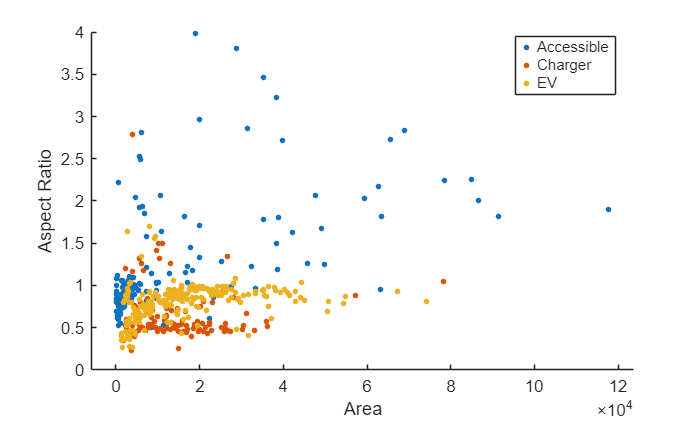

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

### Create box plots of aspect ratios for each class

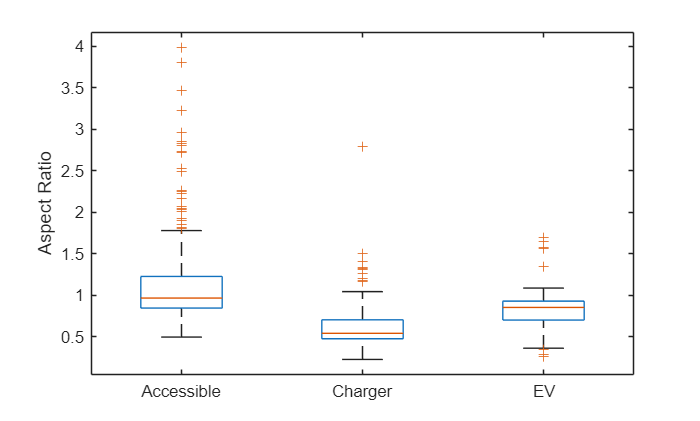

boxplot(bboxes.AspectRatio, bboxes.Label)
ylabel("Aspect Ratio")

### Create a box plot of area for each class

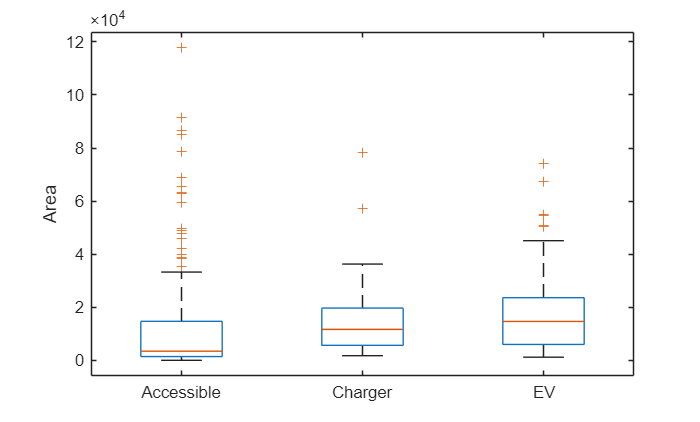

boxplot(bboxes.Area, bboxes.Label)
ylabel("Area")

## Investigate Selected Outliers

Use the drop-down menus below to find the outliers for a specific class and variable. `displayOutlierImage `is a helper function at the bottom of the script that uses your selections to display the outlier object or message to help you set the controls. 

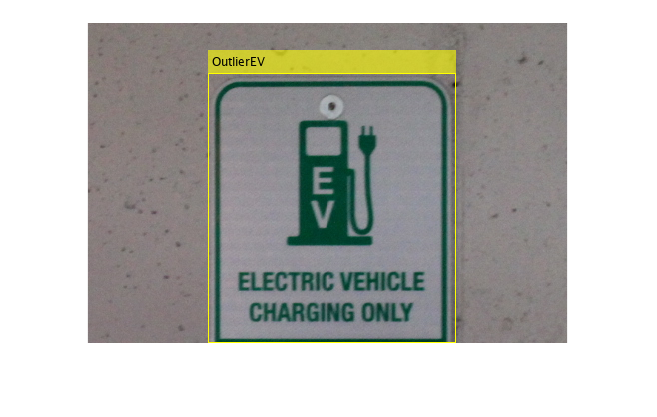

class = "EV";
variable = "Area";
outlier2view = 1;
displayOutlierImage(bboxes, class, variable, outlier2view, imds);

## Helper Functions

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filter the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Find outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Get the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculate the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Check if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Get the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Get the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Read the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Add the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Display the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Display a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Display a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end